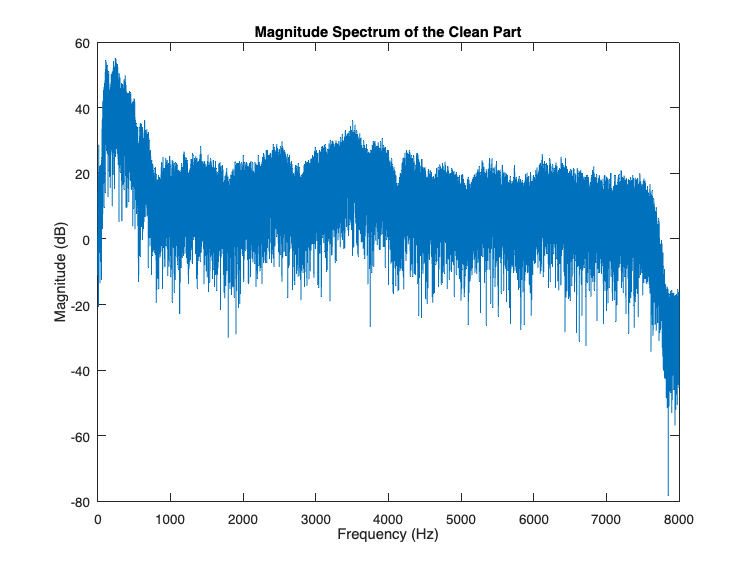

% Step 1: Load and play the corrupted signal
[signal, Fs] = audioread('corrupted.wav');
player = audioplayer(signal, Fs);
%play(player); 

% This will play the audio on your system

% Step 2: Crop the first 14 seconds of the audio into a vector
duration_clean = 14;
signal_clean = signal(1:duration_clean*Fs);

% Step 3: Compute the FFT of the cropped signal and plot
fft_clean = fft(signal_clean);
fft_clean = fft_clean(1:length(signal_clean)/2);
freq_clean = Fs*(0:(length(signal_clean)/2 - 1))/length(signal_clean);
magnitude_clean = 20*log10(abs(fft_clean));

figure;
plot(freq_clean, magnitude_clean);
title('Magnitude Spectrum of the Clean Part');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');


% Step 4: Compute the FFT of the original corrupted signal and plot
fft_corrupted = fft(signal);
fft_corrupted = fft_corrupted(1:length(signal)/2);

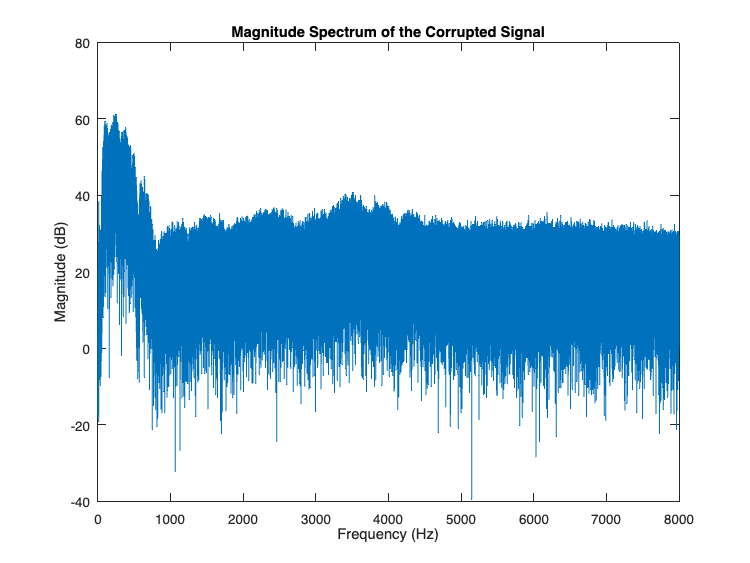

freq_corrupted = Fs*(0:(length(signal)/2 - 1))/length(signal);
magnitude_corrupted = 20*log10(abs(fft_corrupted));

figure;
plot(freq_corrupted, magnitude_corrupted);
title('Magnitude Spectrum of the Corrupted Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');


% Step 5: Design a filter to remove the noise
% Assuming the noise is broadband and not narrowband, we use a lowpass filter
[b, a] = butter(2, 0.05); % Second-order Butterworth filter with cutoff frequency at 5% of Nyquist frequency
disp('Filter Coefficients b:');

Filter Coefficients b:


disp(b);

    0.0055    0.0111    0.0055



disp('Filter Coefficients a:');

Filter Coefficients a:


disp(a);

    1.0000   -1.7786    0.8008



normalized_cutoff = 0.05;  % As used in your butter filter design
cutoff_frequency_hz = normalized_cutoff * (Fs / 2);  % Calculate actual cutoff frequency
fprintf('The cutoff frequency is %.2f Hz\n', cutoff_frequency_hz);

The cutoff frequency is 400.00 Hz


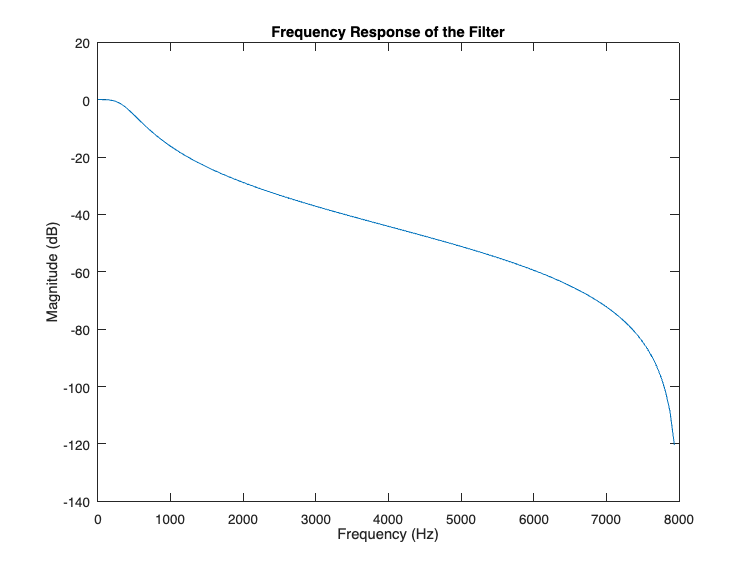

% Plot the frequency response of the filter
[h, w] = freqz(b, a, 128);
figure;
plot(Fs*w/(2*pi), 20*log10(abs(h)));
title('Frequency Response of the Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');


% Step 6: Implement the filter as a difference equation
filtered_signal = filter(b, a, signal);

% Write the filtered signal to a new wav file
audiowrite('filtered_corrupted.wav', filtered_signal, Fs);

% Step 7: Play the filtered signal
player_filtered = audioplayer(filtered_signal, Fs);
play(player_filtered); % This will play the filtered audio on your system

% Step 8: Compute the FFT of the filtered signal and plot
fft_filtered = fft(filtered_signal);
fft_filtered = fft_filtered(1:length(filtered_signal)/2);

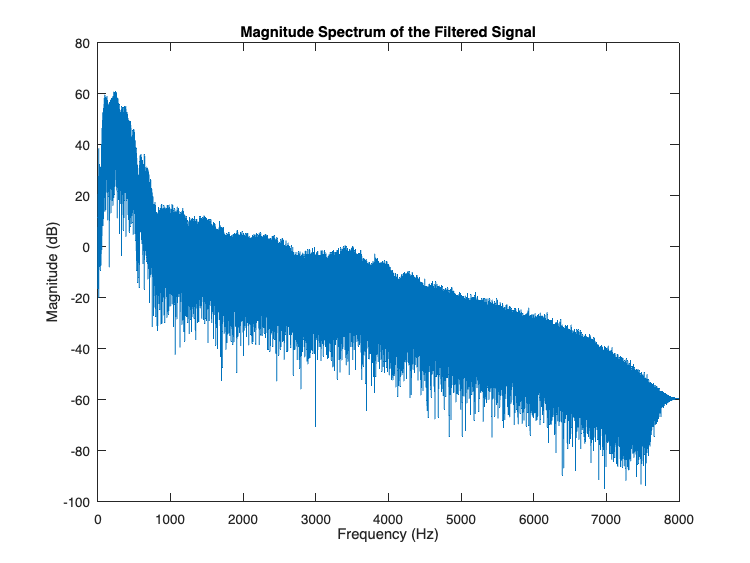

freq_filtered = Fs*(0:(length(filtered_signal)/2 - 1))/length(filtered_signal);
magnitude_filtered = 20*log10(abs(fft_filtered));

figure;
plot(freq_filtered, magnitude_filtered);
title('Magnitude Spectrum of the Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');